# **Continum > Example 02**

**DAE formulation of example 1**

We want to find a Hopf bifurcation point for the following system of equations:

## 
$$\begin{array}{l}
\frac{\textrm{du}}{\textrm{dt}}=1-\mathrm{u}\left(1+\mathrm{Da}\cdot \mathrm{w}\right)\\
\frac{\textrm{dv}}{\textrm{dt}}=\mathrm{B}\cdot \;\textrm{Da}\cdot \;\mathrm{u}\cdot \mathrm{w}-\mathrm{v}\left(1+\textrm{beta}\right)\\
0=\mathrm{w}-{\mathrm{e}}^{\mathrm{v}} 
\end{array}$$


First, we need to create a file in which those equations are implemented:

This file was saved as **cstr_simple_dae.m**

Now, we are able to use the Continum package.

## **1) Create the Variables**

clc
clear

% Syntax: var = Variable(tag, var0);
%         tag is the display name (all tags must be unique).
%         var0 is used as initial guess (steady state solution) or initial condition (dynamic solution).
u = Variable('u', 1);
v = Variable('v', 1);
w = Variable('w', 1);

## 2) Create the Parameters

% Syntax: par = Parameter(tag, par0, lb, ub, fixed); 
%         tag is the display name (all tags must be unique).
%         par0 is used as initial guess.
%         lb is the parameter lower bound.
%         ub is the parameter upper bound.
%         fixed is a boolean: false (default), when the parameter is used in search; true, when it is fixed.
Da = Parameter('Da', 1, 0, 10);
B = Parameter('B', 14, 0, 50, true);
beta = Parameter('beta', 3, 0, 10, true); % This parameter is fixed.

## 3) Create the problem

% The mass matrix
M = [1 0 0; 0 1 0; 0 0 0];

% The problem
P = Continum(@cstr_simple_dae, [u, v, w], [Da, B, beta], M); 
% Variables and parameters's positions must be consistent with the defined in 'cstr_simple.m' file

% Show initial model analysis
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple_dae.m
    Variables ....................................... u = 1, v = 1, w = 1
    Search Parameters ............................... Da = 1
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2


================= End of Report =================



## 4) Simulate

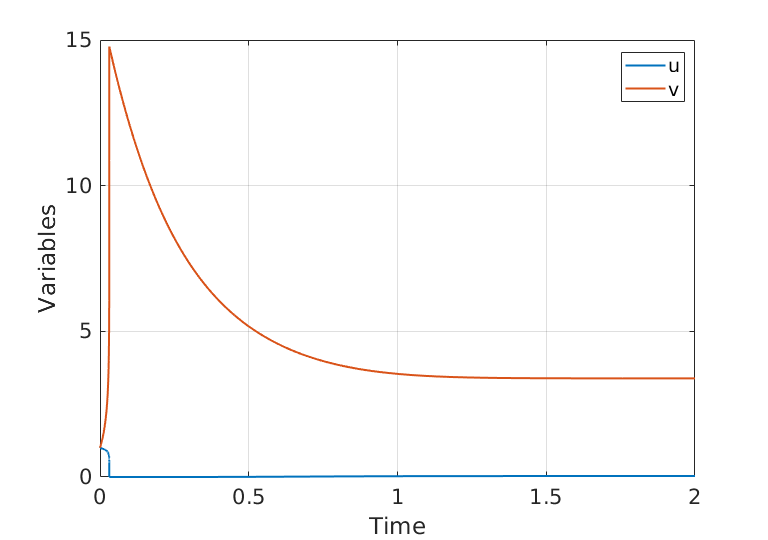

% Setup the integrator:
P.dynopt.abstol = 1e-10;
P.dynopt.reltol = 1e-08;
P.dynopt.solver = 'ode15s';

% Simulate
P.Simulate([0,2]);

% Plot time series
P.PlotTimeSeries([u,v]);

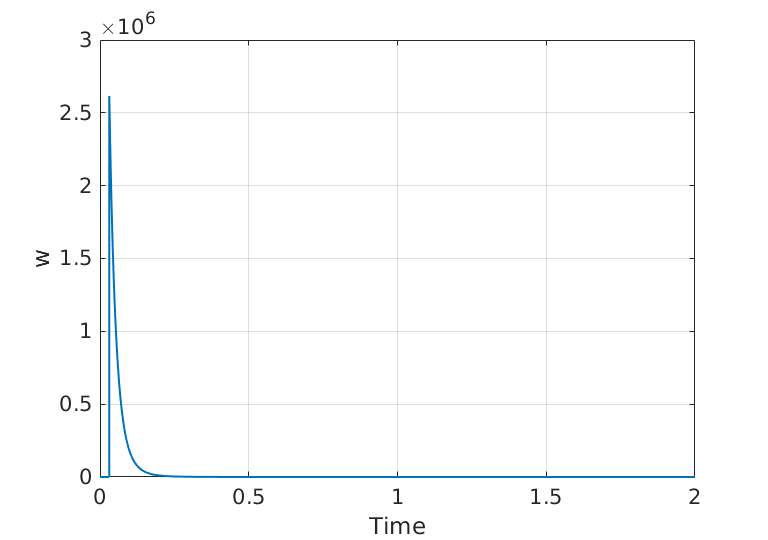

P.PlotTimeSeries(w);

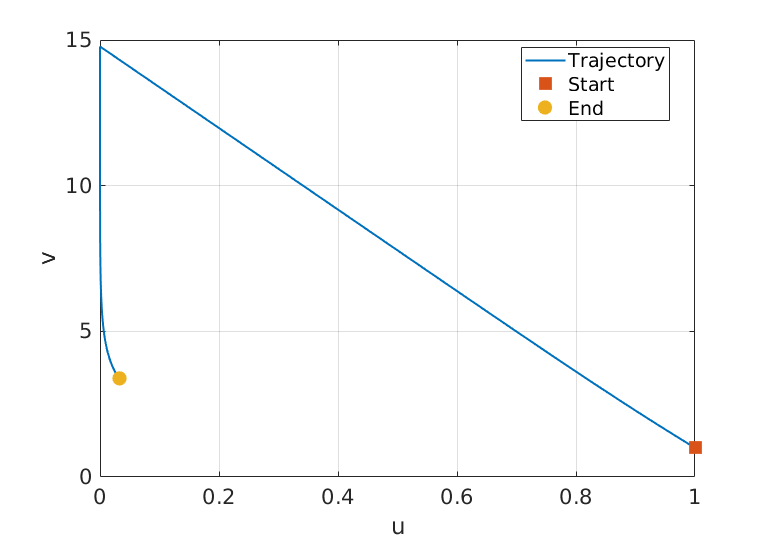


% Plot phase plane
P.PlotPhasePlane(u,v)

## 5) Hopf Search

% Setup optimizer:
P.optopt.algorithm = 'simplex'; % {'simplex','hybrid','swarm','levenberg-marquardt'}
P.optopt.display = 'iter'; % {'none','iter'}
P.optopt.objectiveform = 'absolute'; % {'absolute', 'quadratic'}
P.optopt.tolfun = 1e-10;
P.optopt.tolx = 1e-10;

% HopfSearch
P.HopfSearch;

 
 Iteration   Func-count     min f(x)         Procedure
     0            1           20.987         
     1            4           20.987         initial simplex
     2            6          17.7207         expand
     3            7          17.7207         reflect
     4            9          15.5498         expand
     5           11          10.1596         expand
     6           13          5.91657         expand
     7           15          2.34766         expand
     8           16          2.34766         reflect
     9           18          2.34766         contract inside
    10           20          1.10655         contract outside
    11           22         0.306329         contract inside
    12           23         0.306329         reflect
    13           24         0.306329         reflect
    14           29        0.0503003         shrink
    15           31        0.0503003         contract inside
    16           33        0.0503003         contract outside
    1

P.ShowReport()



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple_dae.m
    Variables ....................................... u = 1, v = 1, w = 1
    Search Parameters ............................... Da = 1
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 1.202411e-01, v = 3.079156e+00, w = 2.174005e+01
    par-values ...................................... Da = 3.365505e-01
    Eigenvalues ..................................... (3.8701e-09 +4.5771e+00i, 3.8701e-09 -4.5771e+00i)

    CPU Time .................................

% Keep the bifurcation point
P.KeepBP;
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple_dae.m
    Variables ....................................... u = 1, v = 1, w = 1
    Search Parameters ............................... Da = 1
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 1.202411e-01, v = 3.079156e+00, w = 2.174005e+01
    par-values ...................................... Da = 3.365505e-01
    Eigenvalues ..................................... (3.8701e-09 +4.5771e+00i, 3.8701e-09 -4.5771e+00i)

    CPU Time .................................

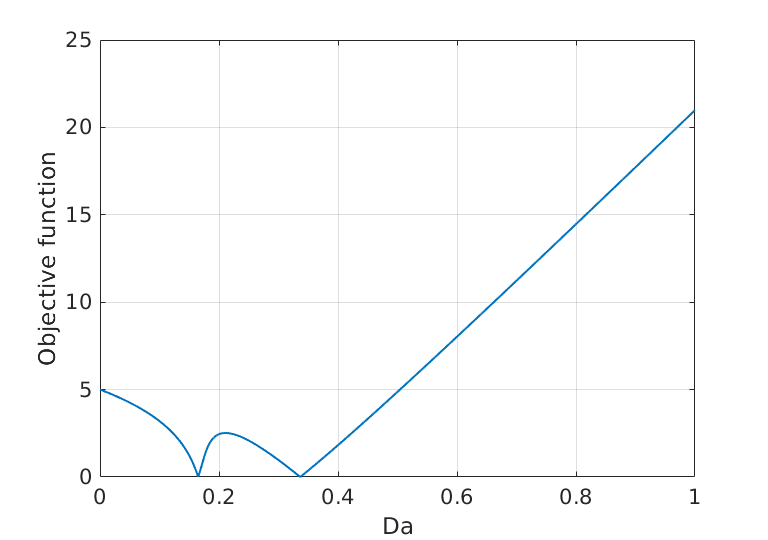

% Plot objective function around hopf for graphical aid
P.PlotObjectiveFunction(Da, 1000, [0 1])

% Change bounds to get another hopf
P.SetUpper(Da, 0.2)


	 Class: Parameter
	 Tag:   Da
	 Value: 2.0000e-01
	 Lower: 0.0000e+00
	 Upper: 2.0000e-01
	 Fixed: no


P.SetValue(Da, 0.1)


	 Class: Parameter
	 Tag:   Da
	 Value: 1.0000e-01
	 Lower: 0.0000e+00
	 Upper: 2.0000e-01
	 Fixed: no


% Make another search
P.HopfSearch;

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          3.19565         
     1            4           3.0595         initial simplex
     2            5           3.0595         reflect
     3            7          2.96418         expand
     4            9          2.70746         expand
     5           11          2.47943         expand
     6           13          1.86291         expand
     7           15          0.33342         expand
     8           17        0.0541728         reflect
     9           19        0.0541728         contract outside
    10           21        0.0541728         contract inside
    11           23        0.0541728         contract inside
    12           25        0.0541728         contract inside
    13           27        0.0541728         contract inside
    14           28        0.0541728         reflect
    15           30        0.0541728         contract inside
    16           32        0.0541728         contr

% New results
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple_dae.m
    Variables ....................................... u = 1.202411e-01, v = 3.079156e+00, w = 2.174005e+01
    Search Parameters ............................... Da = 1.000000e-01
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 5.940446e-01, v = 1.420844e+00, w = 4.140613e+00
    par-values ...................................... Da = 1.650420e-01
    Eigenvalues ..................................... (-3.6170e-09 +1.0248e+00i, -3.6170e-09 -1.0248e+00i)



% Keep new hopf
P.KeepBP;
P.ShowReport



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_simple_dae.m
    Variables ....................................... u = 1.202411e-01, v = 3.079156e+00, w = 2.174005e+01
    Search Parameters ............................... Da = 1.000000e-01
    Fixed Parameters ................................ B = 14, beta = 3

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 2

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ u = 5.940446e-01, v = 1.420844e+00, w = 4.140613e+00
    par-values ...................................... Da = 1.650420e-01
    Eigenvalues ..................................... (-3.6170e-09 +1.0248e+00i, -3.6170e-09 -1.0248e+00i)



## 6) Continuation

% Steady state continuation
P.SSContinuation(Da, 1000, [0.1,0.5])


Runing steady-state continuation...

Iter: 1000	 norm: 0.000000e+00

Finished!

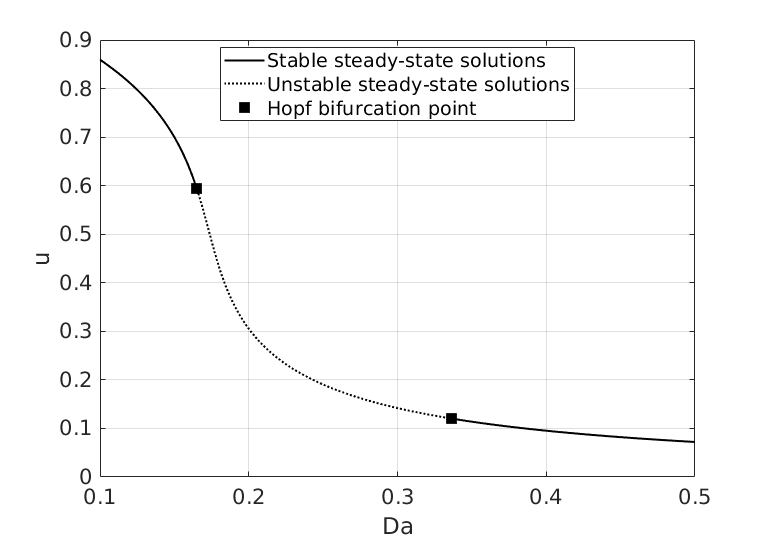

% Plot the branch diagram
P.PlotBranchDiagram(Da, u)

% Periodic continuation
P.ShiftToBP(2)
P.conopt.ds = 1e-3;
P.conopt.fixedDs = false;
P.conopt.kmax = 1500;
P.conopt.algorithm = 'trust-region-reflective';

P.PeriodicContinuation(Da, [], [u,v]);

Searching for initial orbit...


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0        242           1e-06                      0.000145
     1        484     4.52325e-09     0.00562459        0.00329      
     2        726     2.61352e-14     0.00109698       0.000147      
     3        968     1.59265e-19    2.92646e-05       2.72e-06      

Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the selected value
of the function tolerance. However, the last step was ineffective.

<

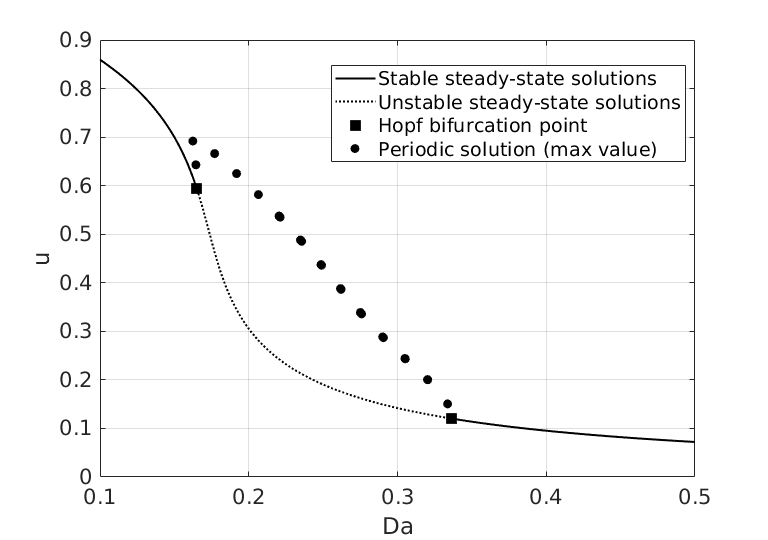

P.PlotBranchDiagram(Da, u)

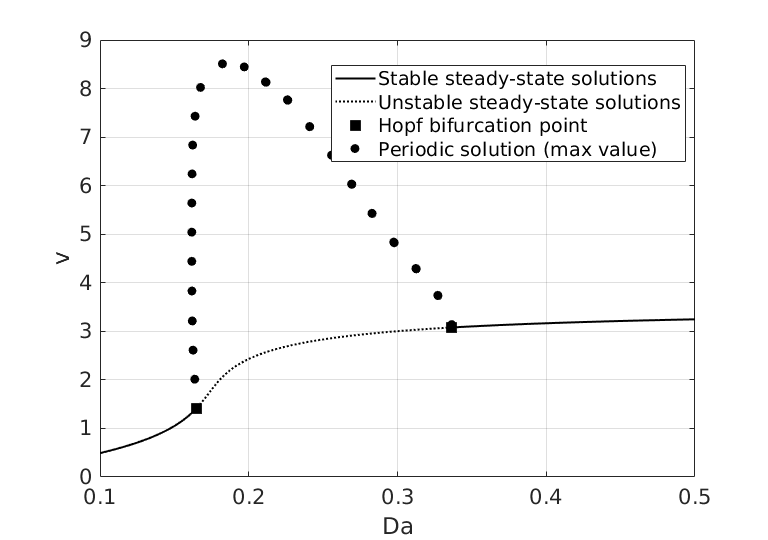

P.PlotBranchDiagram(Da, v)

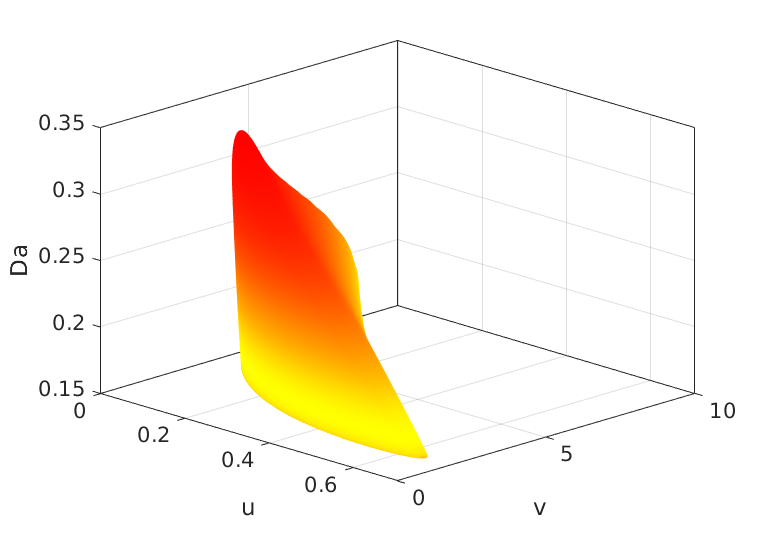

P.PlotOrbitSurface(Da, u, v, [], @autumn)